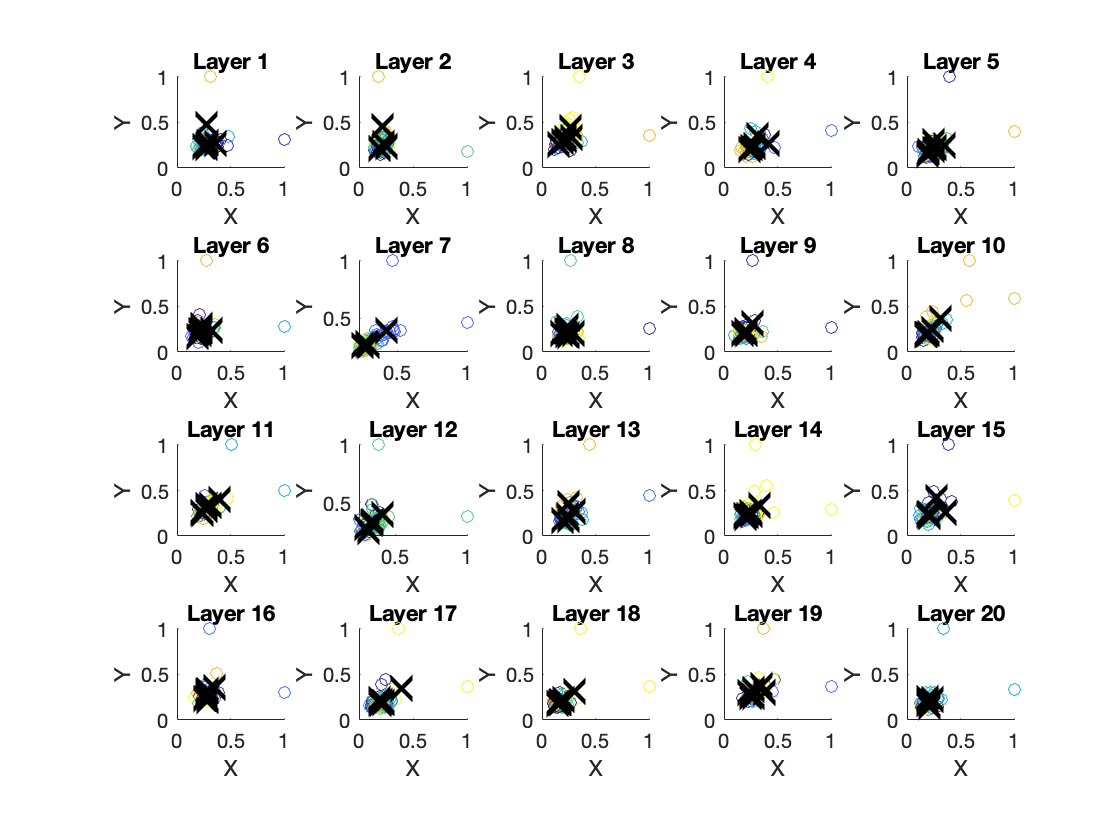

% Load the data

load("findK_eg2_d5_k6.mat", "kc","k","kp", "Z");
%load("FindK_eg_des_take2_d017.mat", "kc","k","kp", "Z");
%load("fixed_k6_kc3_kpl3", "kc","k","kpl");
%kp=kpl;

Al = importdata("theta_theta_all.mat");


load("notFixed_eg2_d5_k6.mat", "ClustersSupra");
L = 20; %20 layers

ClustersSupra = ClustersSupra; %[vertcat(Il{:})];


for l=1:L
    matrix = Al{l};
    % Set the number of clusters (k)
    ks = k(1,l);
    % Perform k-means clustering on the matrix
    [idx,C] = kmeans(matrix, ks);
    
    % Plot the results
    %figure

    %title(['K-means Clustering with k = ', num2str(ks), ', Layer ', num2str(l)])
    
    % Plot the current layer matrix
    subplot(4,5,l);
    scatter(matrix(:,1),matrix(:,2),[],idx)
    hold on
    plot(C(:,1),C(:,2),'kx','MarkerSize',15,'LineWidth',3)
    title(sprintf('Layer %d', l));
    xlabel('X');
    ylabel('Y');
    
end


%highlight(p, find(ClustersSupra==k),'NodeColor', 'r' )